# Beam Deflection

**Learning Goals**

- Solve boundary value problems using symbolic math.

- Identify boundary conditions for different types of beam supports.

- Solve for deflections of loaded beams.

- Visualize beam deflections.

## Beam Deflection Differential Equation

A beam under a load will not only experience bending stress, but also deflect. 

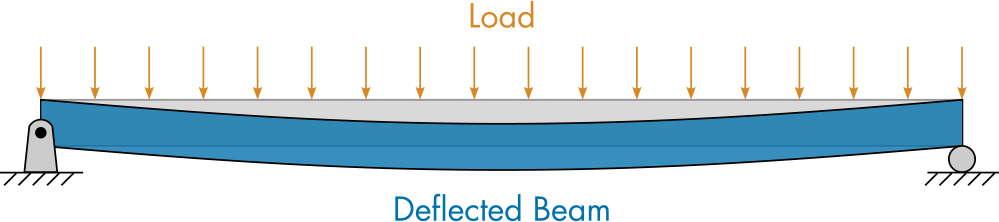

*Beam deflecting under a load*

For most practical cases, deflections are typically small compared to the length of the beam (the maximum deflection is less than 10% of the beam length). In such cases, the deflection along the beam, $v(x)$, may be approximated using


$$\frac{d^2 v}{dx^2} = \frac{M}{EI}$$


where $M = M(x)$ is the moment function, $E$ is the Young's modulus, and $I$ is the area moment of inertia for the cross-section of the beam. In this script, $E$ and $I$ are assumed to be constant (although it would be possible for them to vary with $x$). In addition, only continuous loading functions will be examined. If the loading function has discontinuities, additional steps are required.

## Symbolic Differential Equation Solutions

To solve for the beam deflections, you need to integrate twice. An efficient alternative is to use symbolic math. In this section, you will learn to use the Symbolic Math Toolbox to solve for ODE solutions. This activity follows the same procedure as the examples on the documentation page for [`dsolve`](https://www.mathworks.com/help/symbolic/dsolve.html). If you're having difficulty, consider consulting the documentation examples.

  **Activity 1. **In this activity, you will solve the differential equation 


$$\frac{d^2 u}{dx^2} = x$$


subject to the boundary conditions

$u(0) = 1$    and    $u'(3) = 0$.

**Task 1. **Declare a symbolic function $u(x)$. For example, to declare a symbolic function $z(t)$, you could use

% Write your code here


**Task 2. **Define the differential equation given at the start of this activity using symbolic math and store it in `deq`. To set up the differential equation, you need to take the second derivative of the function $u(x)$, and set that equal to the right-hand-side: $x$. To take the second derivative, use the [`diff`](https://www.mathworks.com/help/symbolic/diff.html) function. For example, to set up the differential equation


$$\frac{d^2 z}{dt^2} = \sin(z)$$


you could use

In this example, the second derivative of $z$ is taken with respect to $t$ and then set equal to $\sin(z)$. Note that `==` is used to represent symbolic equality.

**Task 3. **Create a symbolic array named `bc` with the boundary conditions $u(0) = 1$ and $u'(3) = 0$. For example, to create an array of boundary conditions for $z(1) = 2$ and $z'(0) = -1$, you could use

Notice that you must create a variable for the derivative first and then evaluate the boundary condition.

**Task 4. **Solve the differential equation system you stored in `deq` with the boundary conditions you stored in `bc` using [`dsolve`](https://www.mathworks.com/help/symbolic/dsolve.html). Store the result in `usol`. For example, to solve a differential equation stored in `dfeq` with boundary conditions `bcs`, you could use

**Task 5. **Plot the solution `usol` on the interval $[0,3]$ using [`fplot`](https://www.mathworks.com/help/matlab/ref/fplot.html). 

If correct, your solution should appear as

### 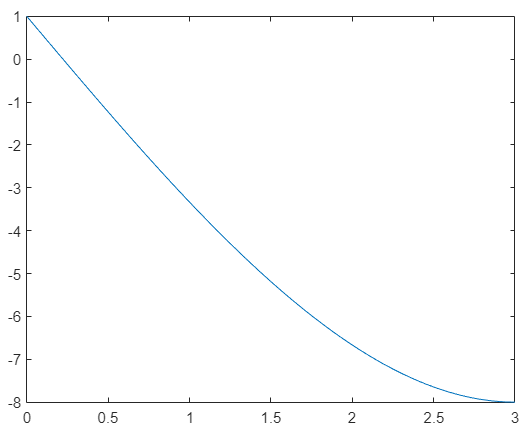

Does the solution satisfy the boundary conditions?

## Solve for Beam Deflections

### Boundary Conditions

You can solve for the beam deflection using the method shown in the previous section. In order to fully define the solution, you will need two boundary conditions. The boundary conditions come from the beam supports. For the pin and roller supports shown above, the deflection (denoted $v(x)$) is zero at the support locations, $x = 0$ and $L$. In mathematical terms: $v(0) = 0$ and $v(L) = 0$.

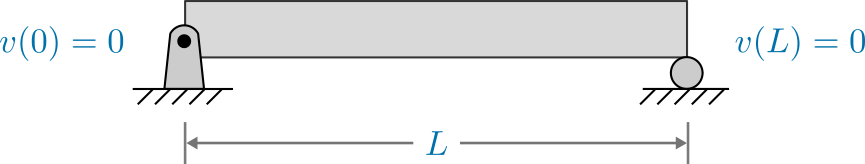

*Boundary conditions for the pin and roller supports.*

For a cantilever beam, only one side is supported. In this case, two boundary conditions are given at the attached boundary: $v(0) = 0$ and $v'(0) = 0$.

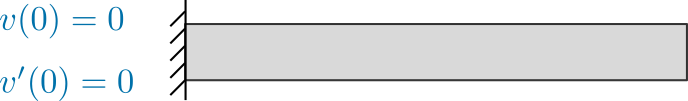

*Boundary conditions of a cantilever beam.*

### Solution Procedure

To solve for the deflection of a loaded beam, there are four steps.

- Solve for the support reactions.

- Solve for moment function, $M(x)$.

- Compute the area moment of inertia $I$ (if it was not given).

- Define and solve the deflection ODE.

The first three steps of this procedure are described in detail in the first part of this module: [*Beam Bending*](matlab:open('./BeamBending.mlx')). Note: the live script must be on the MATLAB Path for this link to work.

 **Example 1.** Solve for the deflection $v(x)$ of the loaded cantilever beam illustrated below.

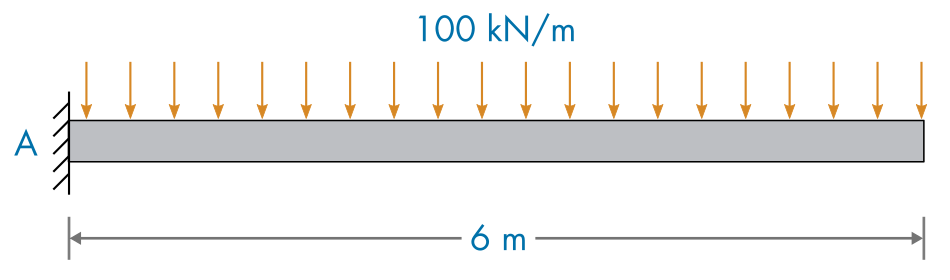

Assume that the beam is rectangular with a cross-sectional height of 30 cm and width of 40 cm. Assume that the beam is made of steel with a Young's modulus $E = 200$ GPa.

**Step 1. Solve for the support reactions.**

To solve for the support reactions, set up equations for the force and moment equilibria. Note that for the cantilever beam, the moment about point $A$ is assumed to be $M_A$, not $F_A \cdot 0$. In the support reaction calculation, the distributed load can be represented as a point force F = (100 kN/m)(6 m) = 600 kN. Because the load is uniform, the resultant force is applied at $x = 3$ m.

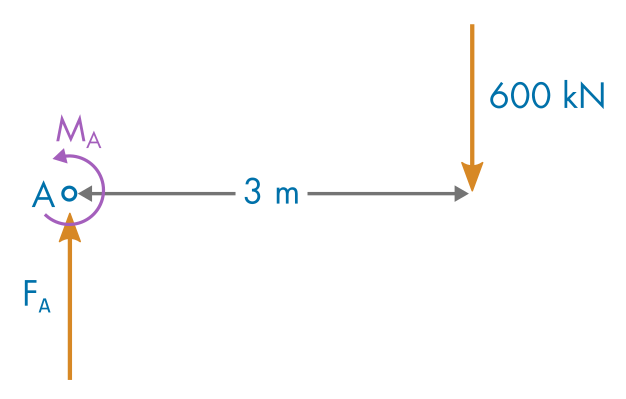

You do not need symbolic math to evaluate these particular expressions.

FA = 100e3*6 % N
MA = 100e3*6*3 % N*m

**Step 2. Solve for moment function, **$M(x)$**.**

First, derive the shear function $s(x)$ along the length of the beam. The functions are defined symbolically.

syms x
s(x) = FA - 100e3*x

The moment function is the integral of the shear function. However, the constant of integration is non-zero because at $x = 0$ there is a point moment. By the equilibrium equation, $M(0) + M_A = 0$, implying $M(0) = -M_A$. Therefore, the moment function is

M(x) = int(s(x)) - MA

It's a helpful check to plot $M(x)$ along the length of the beam after deriving it.

fplot(M(x),[0,6])

You can see that the moment has the greatest magnitude at $x = 0$, since the attachment point supports the full length of the beam.

**Step 3. Compute the area moment of inertia **$I$.

The area moment of inertia for a rectangular beam about the neutral axis is


$$I = \frac{b h^3}{12}$$


b = 0.4; % m
h = 0.3; % m
I = sym(b*h^3/12)

Be sure to define the constant as a symbolic variable by wrapping it in the [`sym`](https://www.mathworks.com/help/symbolic/sym.html) function. Otherwise, the constants may suffer from floating-point errors when being converted to symbolic variables.

**Step 4. Define and solve the deflection ODE.**

First, define the displacement differential equation using the moment function $M(x)$, area moment of inertia $I$, and the given Young's modulus $E$.

E = 200e9; % Pa
syms v(x)
deq = diff(v,x,2) == M(x)/(E*I)

Then, create an array with the boundary conditions for the cantilever beam: $v(0) = v'(0) = 0$.

dv = diff(v,x);
bc = [v(0) == 0, dv(0) == 0];

Now you can solve the differential equation subject to the boundary conditions.

vsol = dsolve(deq,bc)

You can plot the solution for the displacement using `fplot`.

fplot(vsol,[0,6])
xlabel("x (m)")
ylabel("v(x) (m)")

**Exercise 1**. Compute and plot the deflection $v(x)$ of the illustrated cantilever beam.

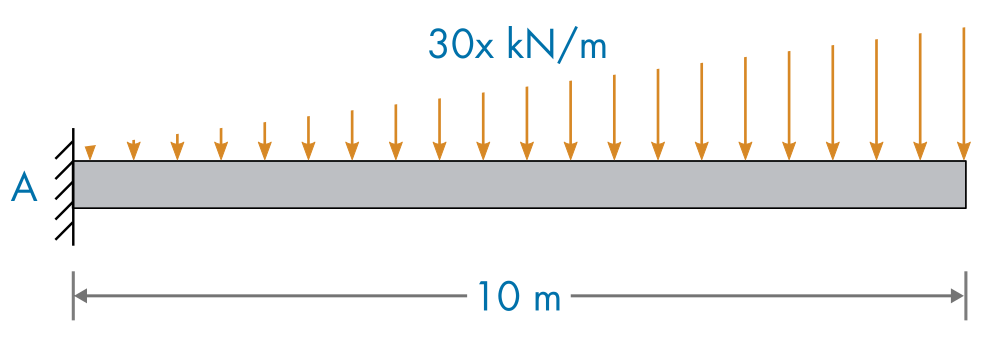

The distributed load is $w(x) = 50x$ kN/m. Assume that the beam is rectangular with a cross-sectional height of 50 cm and a width of 50 cm. Assume that the Young's modulus $E = 205$ GPa.

% Write your code here



 **Example 2.** Solve for the deflection $v(x)$ of the loaded beam illustrated below.

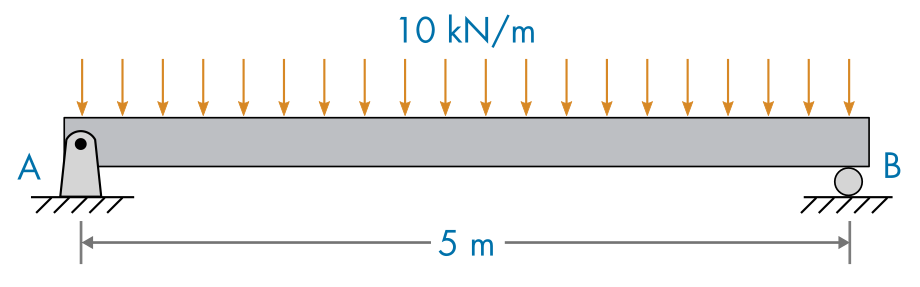

Assume that the beam is rectangular with a cross-sectional height of 20 cm and width of 15 cm. Assume that the beam has a Young's modulus $E = 20$ GPa.

**Step 1-2. Solve for the support reactions and moment function.**

For the details of these steps, see [*Beam Bending: Example 2*](matlab:open('./BeamBending.mlx')). Note: the live script must be on the MATLAB Path for this link to work.

% Support reactions
syms F_A F_B x
eqF = F_A + F_B - int(sym(10e3),0,5) == 0;
eqM = 5*F_B - int(10e3*x,0,5) == 0;
sol = solve(eqF,eqM);
FA = double(sol.F_A)
FB = double(sol.F_B)
% Moment function
S(x) = FA - int(sym(10e3));
M(x) = int(S(x))

** Step 3. Compute the area moment of inertia **$I$.

b = sym(0.15); % m
h = sym(0.20); % m
I = sym(b*h^3/12)

**Step 4. Define and solve the deflection ODE.**

This follows the same procedure as Example 1. Note that the boundary conditions have been changed to $v(0) = v(5) = 0$.

E = 20e9; % Pa
syms v(x)
deq = diff(v,x,2) == M(x)/(E*I);
dv = diff(v,x);
bc = [v(0) == 0, v(5) == 0];
vsol = dsolve(deq,bc)

You can plot the displacement solution using `fplot`.

fplot(vsol,[0,5])
xlabel("x (m)")
ylabel("v(x) (m)")

**Exercise 2**. Compute and plot the deflection $v(x)$ of the loaded beam illustrated below.

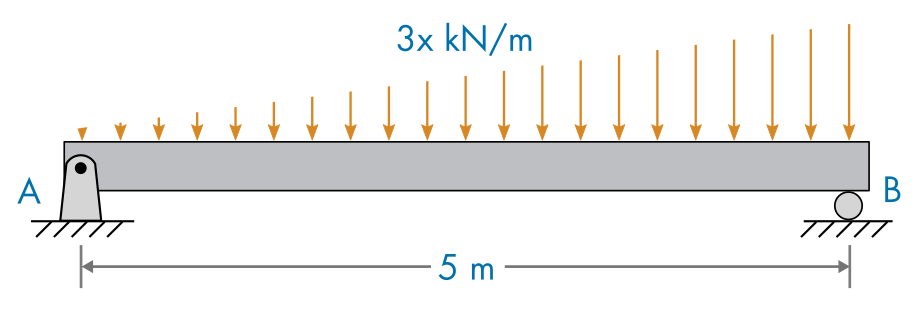

Assume that the beam is rectangular with a cross-sectional height of 10 cm and a width of 50 cm. Also assume that the Young's modulus $E =$ 5 GPa.

% Write your code here



### Visualize Beam Deflections

Symbolic computations are powerful because they can be reused to compute solutions under a variety of conditions. The following activity allows you to reuse code similar to the one you wrote in the previous exercise to compute deflections under various conditions. 

  **Activity 2. **The code below illustrates the deflection together with the shear and moment diagram for a beam with a rectangular cross-section supported on both ends. 

**Task 1. **Run this section to view the default beam deflections.

**Task 2. **Visualize the beam deflections from **Example 2** and **Exercise 2** by adjusting the sliders to match the values in those examples.

syms x
wfunc = -1; % Distributed force function (unitless)
wmag = 50*1e3; % Distributed force multiplier (N)
E = 200*1e9; % Young's modulus (Pa)
L = 10; % Beam length (m)
b = 0.25; % Beam width (m)
h = 0.25; % Beam height (m)
w = sym(wfunc*wmag);
v(x) = deflDiagramSupp(w,E,L,b,h) % Helper function that generates the visualization

**Helper Functions**

function vsol = deflDiagramSupp(w,E,L,b,h)

    %%%% Calculations
    % Moment function
    syms x F_A F_B u v(x)
    w(x) = w;
    eqF = F_A + F_B + int(w(x),x,0,L) == 0;
    eqM = L*F_B + int(w(x)*x,x,0,L) == 0;
    sol = solve([eqF,eqM],[F_A,F_B]);
    FA = sol.F_A;
    FB = sol.F_B;
    S(x) = FA + int(w(u),u,0,x);
    M(x) = int(S(u),u,0,x);

    % Area moment of inertia
    I = sym(b)*sym(h)^3/12;
    
    % Solve for the deflection 
    deq = diff(v,x,2) == M(x)/(E*I);
    bc = [v(0) == 0, v(L) == 0];
    vsol(x) = dsolve(deq,bc);
    
    %%% Figure
    % Build the figure
    figure("Position",[0 0 600 600])
    
    % Bar diagram
    subplot("Position",[0.05,0.7,0.9,0.25])
    
    % Bar diagram
    rollerPos = L;
    pinPos = 0;
    xLims = barDiagramDefl(L,double(FA)/1e3,double(FB)/1e3,w(x)/1e3,rollerPos,pinPos,vsol);
    
    % Shear diagram
    subplot("Position",[0.05,0.4,0.9,0.25])
    shearDiagram(L,xLims,S(x))
    
    % Moment diagram
    subplot("Position",[0.05,0.05,0.9,0.25])
    momentDiagram(L,xLims,M(x))
end

function xLims = barDiagramDefl(length,FA,FB,FappliedSym,rollerPos,pinPos,vsol)
    % Deformation
    xvec = linspace(0,length,300);
    wvec = double(vsol(xvec));
    barHeight = 0.35;
    defAlpha = 0.8;
    defColor = [0 113 170]/255;
    barxdef = [xvec,xvec(end:-1:1)]';
    barydef = [wvec+barHeight,wvec(end:-1:1)]';

    % Force arrow calculations
    maxLength = 10;
    xApplied = linspace(0,maxLength,40);
    Fapplied = double(subs(FappliedSym,xApplied));

    % Settings
    barColor = [0.7 0.7 0.7];
    supportColor = [0.8 0.8 0.8];
    barHeight = 0.35;
    offsetx = 0.0;
    rCirc = 0.1;
    pinHeight = 0.1;
    quiverLW = 1;
    
    circCenter = [rollerPos,-rCirc]; % (xc,yc)
    pinCenter = [pinPos,pinHeight];
    diagramAxisLims = [-rCirc*3,maxLength+rCirc*3,-barHeight,barHeight*2];
    xLims = diagramAxisLims(1:2);
    
    % Bar
    barx = [-offsetx, length+offsetx, length+offsetx, -offsetx];
    bary = [0 0 barHeight barHeight];
    patch(barx,bary,barColor)
    hold on
    % Deformed bar
    patch(barxdef,barydef,defColor,"FaceAlpha",defAlpha)

    % Pin support
    theta = linspace(pi-0.5,0+0.5,50);
    xSupport = rCirc*cos(theta) + pinCenter(1);
    ySupport = rCirc*sin(theta) + pinCenter(2);
    xSupport = [pinPos-0.125, xSupport,pinPos+rCirc*2-0.075];
    ySupport = [-2*rCirc, ySupport, -2*rCirc];
    patch(xSupport,ySupport,supportColor)
    plot(pinCenter(1),pinCenter(2),".",SeriesIndex = "none",MarkerSize = 10)

    % Circle (roller support)
    theta = linspace(0,2*pi,50);
    xcirc = rCirc*cos(theta) + circCenter(1);
    ycirc = rCirc*sin(theta) + circCenter(2);
    patch(xcirc,ycirc,supportColor);    

    % Force scaling
    Fscale = 3*barHeight/max(abs([FA,FB,Fapplied]));

    % Applied force arrow(s)
    vApplied = Fapplied*Fscale;
    yApplied = xApplied*0+barHeight-(vApplied<0).*vApplied;
    idx = xApplied <= length;
    xApplied = xApplied(idx);
    vApplied = vApplied(idx);
    yApplied = yApplied(idx);
    xText = mean(xApplied.*abs(vApplied))./mean(abs(vApplied));
    quiver(xApplied,yApplied,xApplied*0,vApplied,"Autoscale","off",SeriesIndex = 2)

    % Reaction force arrows
    xr = [pinPos, rollerPos];
    vr = [FA*Fscale, FB*Fscale];
    yr = -vr + vr.*(vr < 0);
    quiver(xr,yr,xr*0,vr,"AutoScale","off","LineWidth",quiverLW,SeriesIndex = 2)
    yrText = -abs(vr);
    text(xr,yrText,["F_A = " + num2str(FA,3) + " kN","F_B = " + num2str(FB,3) + " kN"],...
        "HorizontalAlignment","center","VerticalAlignment","top")

    axis(diagramAxisLims)
    axis equal
    axis off

    ax = gca;
    ax.Clipping = "off";

    yAxLims = get(gca,"ylim");
    labelPosY = yAxLims(1) - rCirc;
    % Length label
    xs = sort([0 pinPos rollerPos length]);
    plot(xs,ones(1,4)*labelPosY,"|",SeriesIndex = "none",LineWidth = 1)
    for k = 1:(numel(xs)-1)
        if(abs(diff(xs(k:k+1)))>0)
            xvals = xs(k:k+1) + [0.03,-0.035];
            mx = mean(xvals);
            quiver([mx,mx],[1 1]*labelPosY,[xvals(1)-mx,xvals(2)-mx],[0 0],"Autoscale","Off","MaxHeadSize",0.5/diff(xvals),SeriesIndex = "none")
            text(mean(xvals),labelPosY,num2str(diff(xs(k:k+1))) + " m","BackgroundColor","white",...
                "HorizontalAlignment","center","VerticalAlignment","middle")
        end
    end

    text(xText,yAxLims(2),"F(x) = " + string(FappliedSym) +" [kN/m]",...
        "HorizontalAlignment","center","VerticalAlignment","top")
    hold off
    
end

function shearDiagram(length,xLims,shearForce)

    % Settings
    shearLW = 1;

    % Plot
    fp = fplot(shearForce,[0-1e-2,length+1e-2],"LineWidth",shearLW,SeriesIndex = 1);
    yLims = minmax(fp.YData);
    
    xlabel("x (m)")
    ylabel("Shear (kN)")
    xlim(xLims)
    if(~all(yLims == 0))
        ylim([yLims(1)-diff(yLims)*0.2,yLims(2)+diff(yLims)*0.2])
    end
    xticks([0,length/2,length])
    box off
    ax = gca;
    ax.XAxisLocation = "Origin";
    ax.YAxisLocation = "Origin";
    ax.Clipping = "off";
end

function momentDiagram(length,xLims,moment)

    % Settings
    lw = 1;

    % Plot
    fp = fplot(moment,[0-1e-2,length+1e-2],"LineWidth",lw,SeriesIndex = 4);
    yLims = minmax(fp.YData);
    
    xlabel("x (m)")
    ylabel("Moment (kN·m)")
    xlim(xLims)
    if(~all(yLims == 0))
        ylim([yLims(1)-diff(yLims)*0.2,yLims(2)+diff(yLims)*0.2])
    end
    xticks([0,length/2,length])
    box off
    ax = gca;
    ax.XAxisLocation = "Origin";
    ax.YAxisLocation = "Origin";
    ax.Clipping = "off";
    
end 